# F2020

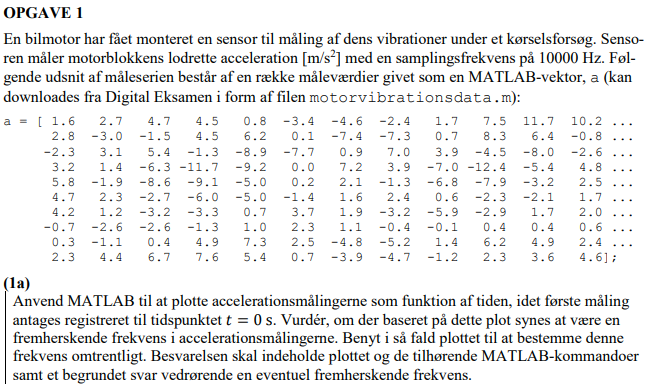

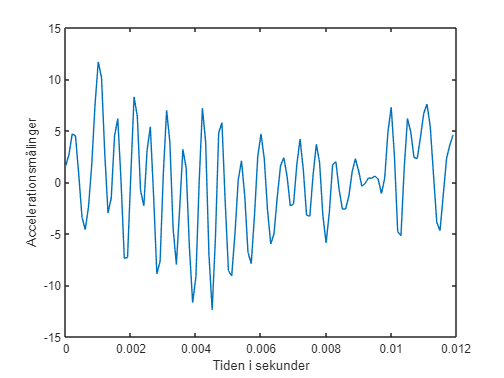

a = [ 1.6 2.7 4.7 4.5 0.8 -3.4 -4.6 -2.4 1.7 7.5 11.7 10.2 ...
 2.8 -3.0 -1.5 4.5 6.2 0.1 -7.4 -7.3 0.7 8.3 6.4 -0.8 ...
 -2.3 3.1 5.4 -1.3 -8.9 -7.7 0.9 7.0 3.9 -4.5 -8.0 -2.6 ...
 3.2 1.4 -6.3 -11.7 -9.2 0.0 7.2 3.9 -7.0 -12.4 -5.4 4.8 ...
 5.8 -1.9 -8.6 -9.1 -5.0 0.2 2.1 -1.3 -6.8 -7.9 -3.2 2.5 ...
 4.7 2.3 -2.7 -6.0 -5.0 -1.4 1.6 2.4 0.6 -2.3 -2.1 1.7 ...
 4.2 1.2 -3.2 -3.3 0.7 3.7 1.9 -3.2 -5.9 -2.9 1.7 2.0 ...
 -0.7 -2.6 -2.6 -1.3 1.0 2.3 1.1 -0.4 -0.1 0.4 0.4 0.6 ...
 0.3 -1.1 0.4 4.9 7.3 2.5 -4.8 -5.2 1.4 6.2 4.9 2.4 ...
 2.3 4.4 6.7 7.6 5.4 0.7 -3.9 -4.7 -1.2 2.3 3.6 4.6]; % 120 målinger

n = length(a);
fs = 10000;
dt = 1/fs;
t = (0:n-1)*dt;
plot(t,a)
ylabel("Accelerationsmålinger")
xlabel("Tiden i sekunder")

Der måles 19 toppe, hvoraf der via grafen i "Open in figure window" er fundet ud af, at den første top har en t = 0.0002, hvoraf den anden top har top ved t = 0.0111.

Dette gør at frekvensen er: $\frac{19}{(0.0111 - 0.0002)} = 1743$

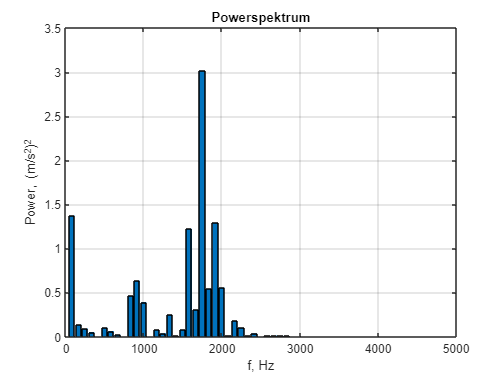

T = n*dt; % Tidsseriens længde (s)
Y = fft(a)/n; % Fast Fouriertransformation
fmax = fs/2; % Højeste detekterbare frekvens (Hz)
df = 1/T; % Afstand mellem detekterbare frekvenser (Hz)
P = real(Y).^2 + imag(Y).^2; % Beregn vektor af power-værdier
f = (0:n-1)*df; % Frekvenser
figure
bar(f,P);
xlim([0 fmax]); % Afgræns frekvensaksen
xlabel('f, Hz'); ylabel('Power, (m/s^2)^2');
title('Powerspektrum');
grid


res = find(P==max(P)) % Søger efter punktet hvor P er størst, hvoraf der fremkommer et real & imaginær resultat.

res =     22   100


Dhz = f(res(1)); % 1750

Opgave 1.C

clear
f = 0:200:5000;
P = [0.00 0.26 0.24 0.65 1.97 0.32 0.04 0.00 0.90 ...
 1.44 3.60 0.08 0.58 0.06 0.09 0.10 0.04 0.06 ...
 0.06 0.05 0.05 0.05 0.05 0.05 0.04 0.05];
N = length(P);
fprintf('f, Hz P, (m/s^2)^2\n')

f, Hz P, (m/s^2)^2


for i = 2:N-1
 if P(i) > P(i-1) && P(i) > P(i+1)
 fprintf('%5.0f %6.4f\n',f(i),P(i))
 end
end

  200 0.2600
  800 1.9700
 2000 3.6000
 2400 0.5800
 3000 0.1000


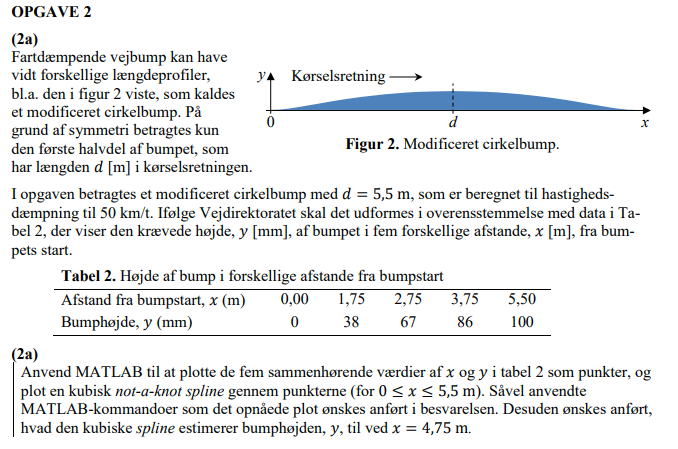

x = [0 1.75 2.75 3.75 5.5]; % Afstand fra bump i meter.
y = [0 38 67 86 100];       % Bumphøjde i mm.
N = linspace(0,5.5,length(x)*100);
yy = spline(x,y,N);
yguess = spline(x,y,4.75)

yguess = 95.9710

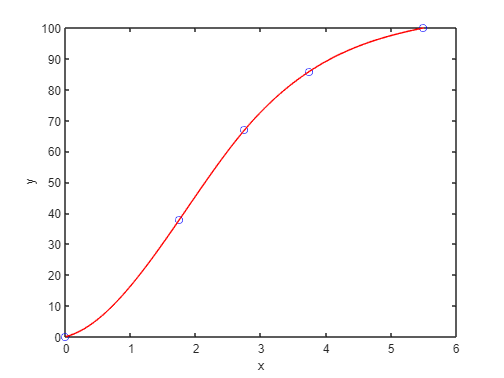

plot(x,y,'bo',N,yy,'r');
xlabel('x'); 
ylabel('y');

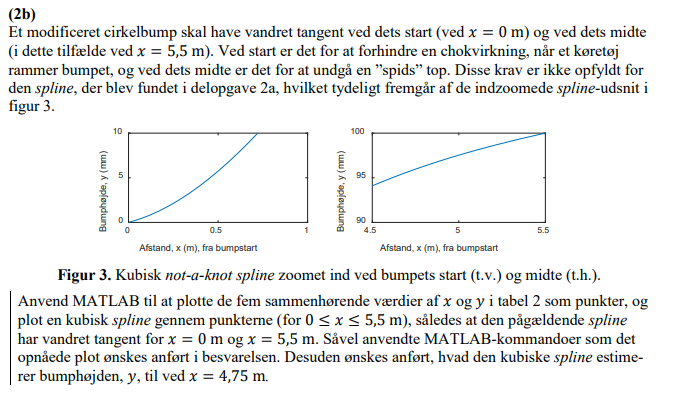

clear
x = [0 1.75 2.75 3.75 5.5]; % Afstand fra bump i meter.
y = [0 38 67 86 100];       % Bumphøjde i mm.
y_some = [0 y 0]           % 

y_some =      0     0    38    67    86   100     0


N = linspace(0,5.5,length(x)*100);
yy = spline(x,y_some,N);
yguess = spline(x,y_some,4.75)

yguess = 97.1982

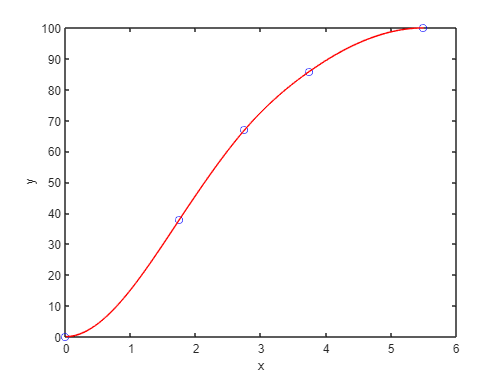

plot(x,y,'bo',N,yy,'r');
xlabel('x'); 
ylabel('y');

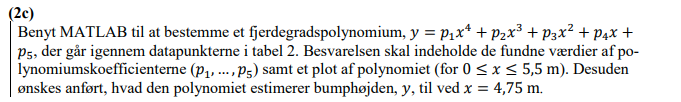

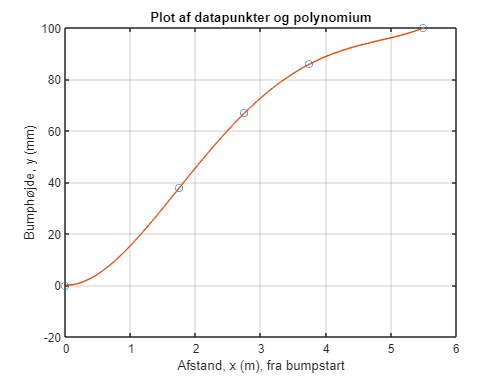

clear
x = [0 1.75 2.75 3.75 5.5]; % Afstand fra bump i meter.
y = [0 38 67 86 100];       % Bumphøjde i mm.
p = polyfit(x,y,4);
N = linspace(0,5.5,length(x)*100);
yy = polyval(p,N);
plot(x,y,'o',N,yy) % Plot af datapunkter og polynomium
title('Plot af datapunkter og polynomium')
xlabel('Afstand, x (m), fra bumpstart')
ylabel('Bumphøjde, y (mm)')
grid

help spline

 spline Cubic spline data interpolation.
    YQ = spline(X,Y,XQ) performs cubic spline interpolation using the
    values Y at sample points X to find interpolated values YQ at the query
    points XQ.
        - X must be a vector.
        - If Y is a vector, Y(j) is the value at X(j).
        - If Y is a matrix or n-D array, Y(:,...,:,j) is the value at X(j).
 
    spline chooses slopes at X(j) such that YQ has a continuous second
    derivative. Thus, spline produces smooth results.
 
    Ordinarily, spline uses not-a-knot conditions for the end slopes at
    X(1) and X(end). However, if Y contains two more values than X has
    entries, then the first and last value in Y are used as the end slopes.
 
    PP = spline(X,Y) returns the piecewise polynomial form PP of the
    interpolant. You can use PP as an input to PPVAL or UNMKPP.
 
    Comparison of spline, PCHIP, 

polyval(p,4.75)

ans = 94.7129

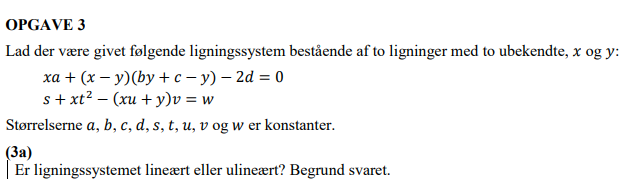

Lignings systemet er ulineært. Dette kan ses på nedenstå opsatte jacobian matrise, hvor den øverste række indeholder vores ubekendt fortsat, hvor af ligningssytemet er ulineært.

clear
syms x y a b c d v w t s u
aa = [x*a+(x-y)*(b*y+c-y)-2*d
    s+x*t^2-(x*u+y)*v-w];
jacobian(aa,[x,y])

$$ans = \left(\begin{array}{cc} a+c-y+b\,y & y-c-b\,y+\left(x-y\right)\,\left(b-1\right)\\ t^{2}-u\,v & -v \end{array}\right)$$

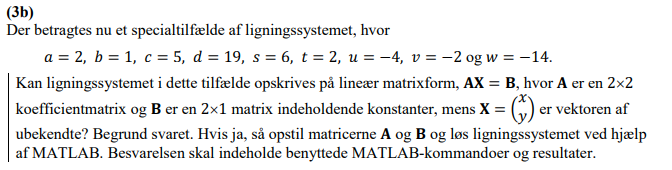

Ved start testes systemet via jacobian, hvor af output kommer ud som konstanter, hvilket betyder, at vores ligningssytem er lineært.

clear
syms x y
a = 2;
b = 1;
c = 5;
d = 19;
s = 6;
t = 2;
u = -4;
v = -2;
w = -14;
aa = [x*a+(x-y)*(b*y+c-y)-2*d
    s+x*t^2-(x*u+y)*v-w]

$$aa = \left(\begin{array}{c} 7\,x-5\,y-38\\ 2\,y-4\,x+20 \end{array}\right)$$

jacobian(aa,[x,y])

$$ans = \left(\begin{array}{cc} 7 & -5\\ -4 & 2 \end{array}\right)$$

% -----------------------------------
A = [7 -5;-4 2];
B = [38;-20];
x = A\B

x =     4.0000
   -2.0000


X = x(1)

X = 4.0000

Y = x(2)

Y = -2.0000

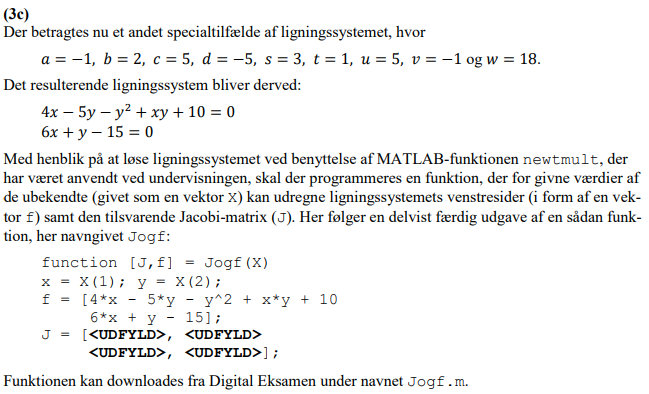

syms x y
f = [4*x - 5*y - y^2 + x*y + 10
    6*x + y - 15];
jacobian(f,[x,y])

$$ans = \left(\begin{array}{cc} y+4 & x-2\,y-5\\ 6 & 1 \end{array}\right)$$

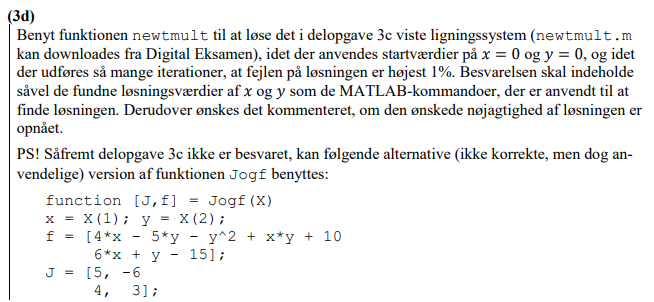

clear
[x, f, ea, iter] = newtmult(@Jogf,[0;0],1)

x =     2.0000
    3.0001


f =    -0.2925
         0


ea = 0.9528

iter = 3